Zad 1. Bez ograniczeń

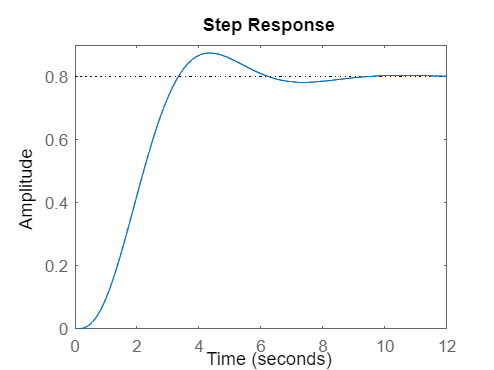

clear;

Gs_Licz=[0 1];
Gs_Mian=poly([-0.5+1i, -0.5-1i, -1]);
Gs=tf(Gs_Licz,Gs_Mian);
step(Gs);

[Gs2_Licz,Gs2_Mian]=pade(0.5,3);
Gs2=tf(Gs2_Licz,Gs2_Mian);
Gs2=Gs*Gs2

Gs2 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.



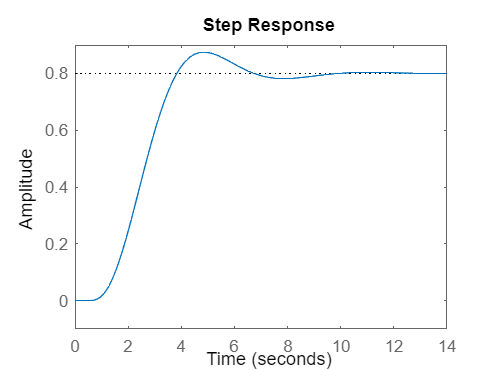

step(Gs2);

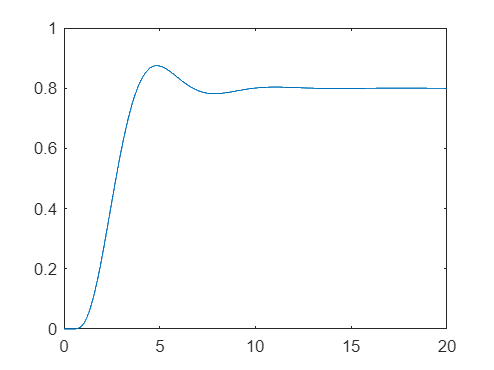


% Obiekt rzeczywisty - estymowany
global t; global y1;
Go = Gs2;
t=0:0.01:20;
y1 = step(t, Go);
plot(t, y1);


x0 = [0,0,0,1]; 
fun = @ident;
%------
A = []; % No other constraints
b = [];
Aeq = [];
beq = [];
%lb = [0, 0, 0, 0];
%ub = [100, 100, 100, 100];
lb=[]


lb =

     []



ub=[]


ub =

     []




Single objective optimization:
4 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationgaussian

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100           129.3      7.758e+116        0
    2              147           129.3      1.094e+247        1
    3              194           120.8       4.58e+106        0
    4              241           68.68       1.295e+60        0
    5              288           68.68      2.346e+136        1
    6              335           68.68      2.346e+136        2
    7              382           68.68      2.192e+136        3
    8              429           68.68      1.588e+167        4
    9              476           68.68      4.816e+172        5
   10              523           68.68      4.719e+172        6
   11           

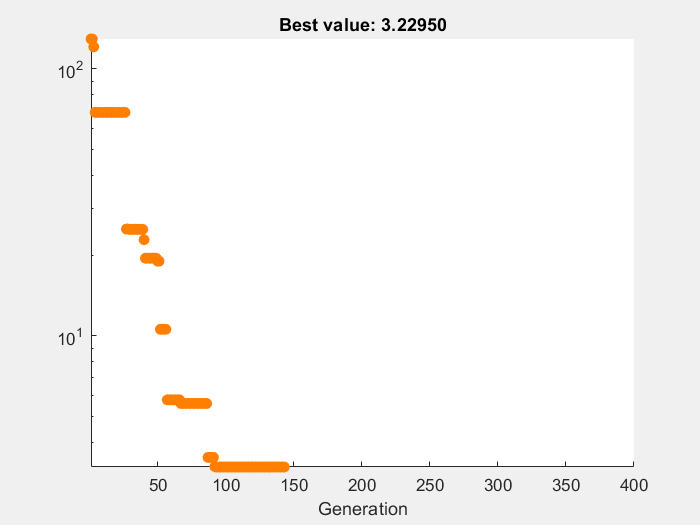

nonlcon = [];
intcon = [];
options = optimoptions("ga",'PlotFcn',{@gaplotchange}, 'Display','iter');
options.InitialPopulationMatrix = x0;
[x, fval, exitflag] = ga(fun, 4, A, b, Aeq, beq, lb, ub, nonlcon, intcon, options);


% Obiekt estymujący G1
G2=tf([0 1],[x(1) x(2) x(3) x(4)])

G2 =
 
                   1
  ------------------------------------
  0.3874 s^3 + 2.369 s^2 + 1.975 s + 1
 
Continuous-time transfer function.




step(G2)

%b=G2.Numerator{1, 1}
%a=G2.Denominator{1,1}
%[z,p,k] =tf2zp(b,a)


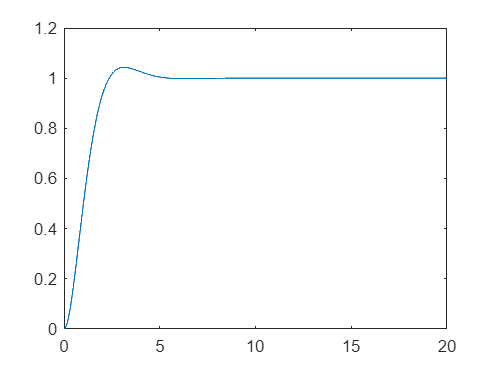

clear;
global Go; global t; global y1;
% Definicja obiektu sterowania
Gk_model = tf([0 2], [1 2 2]);
Go = tf([0 1], [1 2 2.25 1.25]);
t = 0:0.01:20;
y1 = step(t, Gk_model);
plot(t, y1);


% Ograniczenia równościowe
a = [];
b = [];
Aeq = [];
beq = [];

% Warunek początkowy
x0 = [0, 0, 1];

fun = @identPID;
intcon = [];

options = optimoptions("ga",'PlotFcn',{@gaplotchange}, 'Display','iter');
options.InitialPopulationMatrix = x0;

Bez ograniczeń

lb=[]


lb =

     []



ub=[]


ub =

     []




Single objective optimization:
3 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationgaussian

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100           41.41       4.077e+72        0
    2              147           41.41       1.242e+67        1
    3              194           41.41       5.286e+61        2
    4              241           41.41       4.551e+59        3
    5              288           41.41       1.167e+48        4
    6              335           41.41       9.348e+62        5
    7              382           41.41       1.043e+73        6
    8              429           41.41      8.431e+101        7
    9              476           41.41      4.942e+101        8
   10              523           38.36      3.657e+107        0
   11           

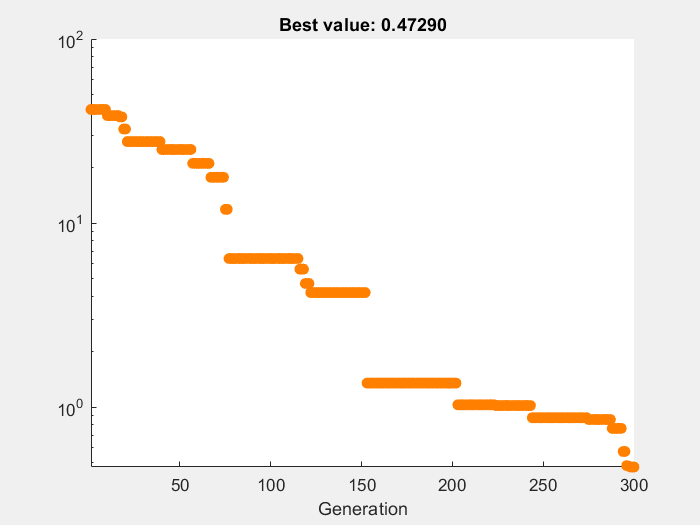

nonlcon = [];

[optimal_params, fval, exitflag] = ga(fun, 3, a, b, Aeq, beq, lb, ub, nonlcon, intcon, options);


% Wyświetlenie wyników optymalizacji
disp('Optymalne wartości Kp, Ki, Kd:')

Optymalne wartości Kp, Ki, Kd:


disp(optimal_params);

    1.2969    1.2764    1.4516




% Wyświetlenie wartości funkcji celu dla optymalnych parametrów
disp('Wartość funkcji celu dla optymalnych parametrów:')

Wartość funkcji celu dla optymalnych parametrów:


disp(fval);

    0.4729



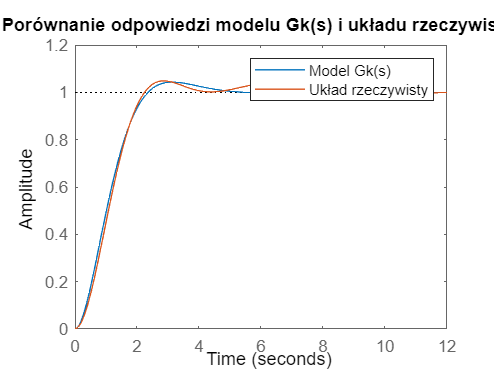


% Wyświetlenie porównania odpowiedzi układu rzeczywistego i modelu
figure;
step(Gk_model, feedback(Go*pid(optimal_params(1), optimal_params(2), optimal_params(3)), 1));
legend('Model Gk(s)', 'Układ rzeczywisty');
title('Porównanie odpowiedzi modelu Gk(s) i układu rzeczywistego');

Z ograniczeniami

% Ograniczenia na nastawy regulatora
lb = [0.2, 0.2, 0.2];
ub = [5, 10, 10];

%nonlcon = @Hurwitz;
nonlcon = [];

[optimal_params, fval, exitflag] = ga(fun, 3, a, b, Aeq, beq, lb, ub, nonlcon, intcon, options);


Single objective optimization:
3 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100           2.355       1.231e+07        0
    2              147           2.355       1.399e+04        1
    3              194           2.355       1.864e+05        2
    4              241          0.9699            1081        0
    5              288          0.9699           210.9        1
    6              335          0.9699           6.361        2
    7              382          0.7408           21.12        0
    8              429          0.6735           1.821        0
    9              476          0.6735           2.912        1
   10              523            0.65           2.509        0
   11      


% Wyświetlenie wyników
disp('Optymalne nastawy regulatora PID:');

Optymalne nastawy regulatora PID:


disp(optimal_params);

    1.3118    1.3115    1.4698




% Wyświetlenie wartości funkcji celu
disp('Wartość funkcji celu:');

Wartość funkcji celu:


disp(fval);

    0.4501



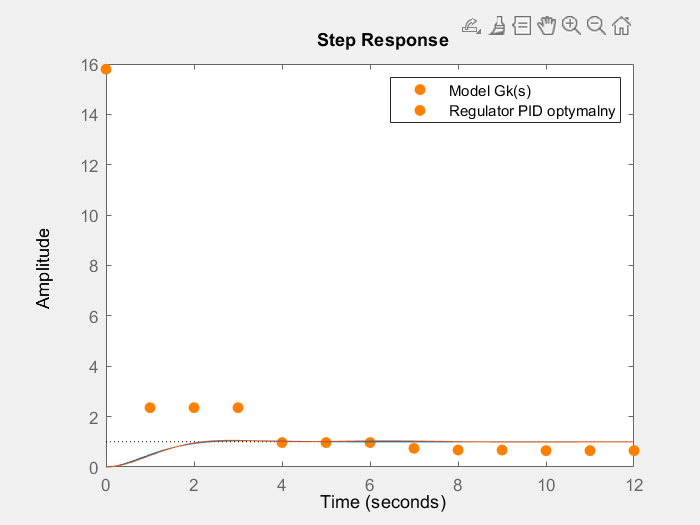


% Symulacja układu z optymalnymi parametrami
step(Gk_model, feedback(Go*pid(optimal_params(1), optimal_params(2), optimal_params(3)), 1));
legend('Model Gk(s)', 'Regulator PID optymalny');


% funkcja gm zwraca zapas modułu

function blad = identPID(x)
    global Go; global t; global y1;
    
    G2 = feedback(Go*pid(x(1), x(2), x(3)), 1);
    y2 = step(G2, t); % dopasowanie

    e = y1-y2;
    blad= sum(e.^2);
    %blad= sum(e.^2) / length(e);
end

function [c,ceq] = Hurwitz(x)
    global Go;

    G2 = feedback(Go*pid(x(1), x(2), x(3)), 1);
    x = G2.Denominator{1};

    H=[x(2) x(4)  0 0 ; x(1) x(3) x(5) 0 ; 0 x(2) x(4) 0 ; 0 x(1) x(3) x(5)];
    H1=H(1,1);
    H2=H(1:2,1:2);
    H3=H(1:3, 1:3);

    Det_H1=det(H1);
    Det_H2=det(H2);
    Det_H3 = det(H3);
    Det_H=det(H);
    

    c(1) = -Det_H1;
    c(2) = -Det_H2;
    c(3) = -Det_H3;
    c(4) = -Det_H;
    ceq = [];

end

function blad = ident(x)
    global t; global y1;

    k = 0.8; % Odczytane z odpowiedzi skokowej G1
    T1 = x(1); T2 = x(2); T3 = x(3); c = x(4);

    G2 = tf([0 k], [T1 T2 T3 c]);
    y2 = step(G2,t); % dopasowanie

    e = y1-y2;
    blad= sum(e.^2);
    %blad= sum(e.^2) / length(e);
end

function [c,ceq] = ellipseparabola(x)  % funkcja ograniczeń nieliniowych
    c(1) = (x(1)^2)/9 + (x(2)^2)/4 - 1;
    c(2) = x(1)^2 - x(2) - 1;
    ceq = [];
end

function state = gaplotchange(options, state, flag)
    persistent last_best
    if(strcmp(flag,'init'))
    xlim([1,options.MaxGenerations]);
    axx = gca;
    axx.YScale = 'log';
    hold on;
    xlabel Generation
    X = sprintf('Best value: %.5f', min(state.Score));
    title(X)
    end
    X = sprintf('Best value: %.5f', min(state.Score));
    title(X)
    best = min(state.Score);
    plot(state.Generation,best,'o', 'MarkerFaceColor',[1 0.5 0], ...
    'MarkerEdgeColor', [1 0.5 0]);
end